# **IO334 - Analog Loopback**

This example demonstrates using the analog I/O of the IO334 in single sampling mode. The timing is defined by the CPU model execution. The Analog to Digital Converters (ADC) and Digital to Analog Converters (DAC) are sampled or updated once per model step. The required driver blocks and settings are described below. The example generates sine wave signals on the analog outputs. The analog output pins of the module must be wired to the analog input pins to feed back the signals into the model for logging and visualization.

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with one IO334 I/O module installed

- A Speedgoat configuration file for the IO334 module

- Connector cable from the I/O module to the terminal board

- 1x 100-pin terminal board with jumper wires

- Optional: Oscilloscope to measure the analog signals

### Test Setup

Connect the IO334 module with the cable to the 100-pin terminal board. Note the indications on the connectors of the cable to make sure the right connector is connected to the I/O module and terminal board respectively (the cable is not symmetrical). The arrows on the connectors help to make sure that the orientation is right. Locate the DAC channels 1 to 4 and connect them to the differential analog input channels 1 and 2 according to the table below. The example model uses two single-ended analog outputs to generate one differential signal. Therefore, the sine waves connected to analog output channels 2 and 4 are of opposite phase compared to channels 1 and 3.

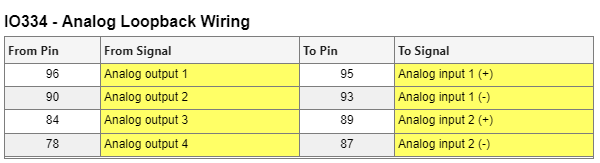

The complete pin mapping is available in [IO334 Pin Mapping](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io334_325k_pin_mapping).

## Initialize and Open the Simulink model

Open the Simulink model manually or use the following commands.

 
% Open Simulink model
modelName = 'sgMdl_IO334_AnalogLoopback';
open_system(modelName);

Before the Simulink model can be built, the I/O module and configuration file must be specified in the IO3xx Setup block, as this example can be executed on different configurable I/O modules. First, open the mask of the IO3xx Setup block and select your I/O module from the drop-down. Once the mask has extended, select a configuration file. This example only requires analog interfaces, which are supported by any configuration file for the IO334 by default.

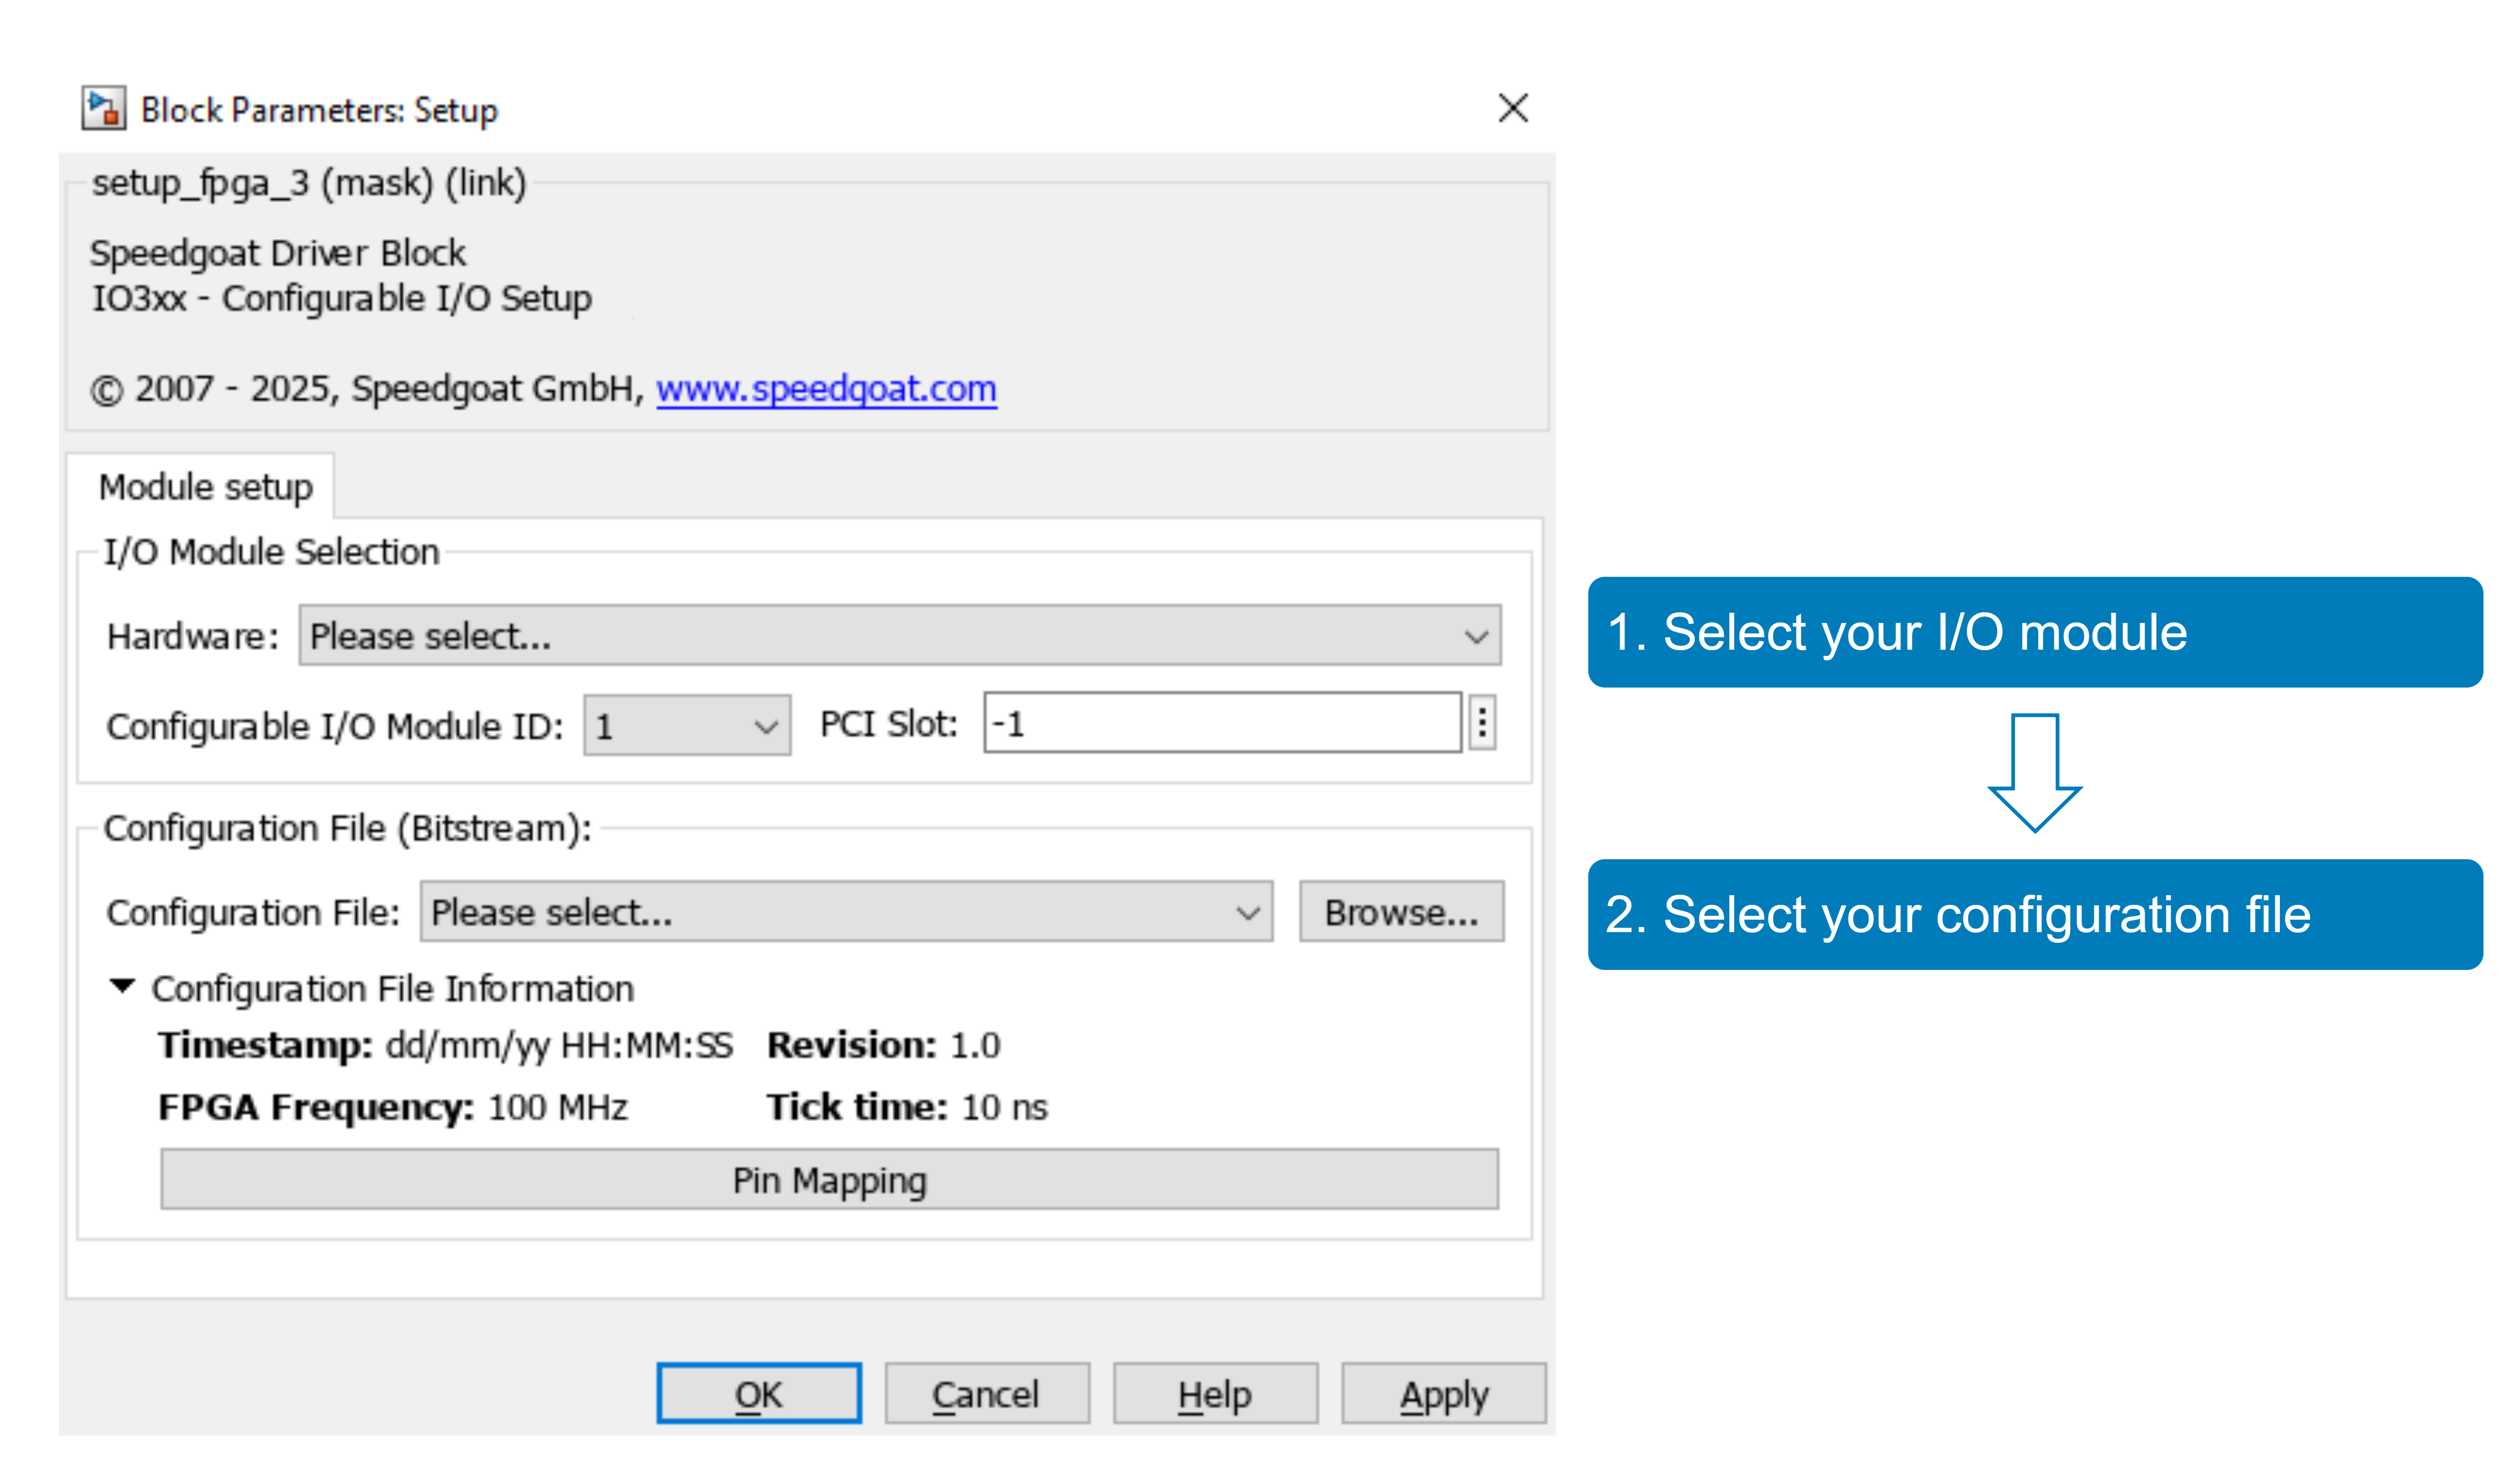

With the **Pin Mapping** button you can now check where the functionalities are located.

## Model Description

### General Setup

The Simulink model features the [IO3xx Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_fpga_setup_io334_325k), [IO334 Analog Setup v1](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io334_analog_setup_v1), [IO334 Analog Input v1](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io334_analog_input_v1), and [IO334 Analog Output v1](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io334_analog_output_v1) blocks. The analog inputs and outputs are configured in the [IO334 Analog Setup v1](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io334_analog_setup_v1) block. In this example, the ADCs and the DACs run in single sample mode. The ADCs and DACs are sampled and updated once per CPU model sample step. The timing is defined by the CPU model step. The sampling happens when the driver block is executed on the CPU.

The analog outputs of the IO334 are single ended. Note that the analog input circuits expect differential signals. The example model uses 4 analog output channels to generate two quasi-differential sine wave signals. The Sine Wave block is used to generate two signals with an amplitude of 1 and 2 V respectively. In the subsystem named "Create Diff. Signal", the signals are transformed to two pairs of differential signals. Therefore, the sine waves on analog output channels 2 and 4 are of opposite phase (multiplied by -1) than channels 1 and 3. The analog input channels 1 and 2 are used to read back the signals for logging and visualization. 

The [IO334 Analog Output v1](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io334_analog_output_v1) block is located within the enabled subsystem to demonstrate the behavior of the initial state parameter. The block is not called during the first 500 ms of the simulation.

Some settings are shared between the [IO3xx Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_fpga_setup_io334_325k), [IO334 Analog Setup v1](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io334_analog_setup_v1), [IO334 Analog Input v1](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io334_analog_input_v1), and [IO334 Analog Output v1](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io334_analog_output_v1) blocks. Ensure that you select the same FPGA Module Identifier in the mask of these blocks. This is important for Simulink to identify which blocks belong together and which I/O module they address. This is especially important if you have multiple configurable I/O modules in your system.

### ADC (Analog Inputs) and DAC (Analog Outputs) Settings

To see the setup and parametrization of the ADC and DAC channels, open the [IO334 Analog Setup v1](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io334_analog_setup_v1) block.

#### Tab: Main

In the main tab of the [IO334 Analog Setup v1](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io334_analog_setup_v1) block, the **ADC Sample Trigger** and **DAC Sample Trigger** parameters are both set to **Model Step**. This model does one ADC and DAC conversion per model step for each channel.

The **Read Value From Previous Model Step** checkbox is not selected. This setting concerns the analog inputs. A new sample is triggered each model step. The CPU waits to receive the sampled data of the current time step. You can enable the checkbox to reduce the Task Execution Time of the model. The CPU will then trigger a sample every model step, but will read the sample which was triggered at the previous step. This avoids the CPU having to wait for the latest data.

#### Tab: Analog Inputs

In the **Analog Inputs** tab of the [IO334 Analog Setup v1](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io334_analog_setup_v1) block, you can see which ADC channels are active, and the configured voltage range. In this example, ADC channels 1 and 2 are used. Note that all analog inputs of the IO334 expect differential signals. The voltage range is +/-10 V (or +/- 2.5 V, depending on the hardware variant), which refers to the differential signal range. 

#### Tab: Analog Outputs

In the **Analog Outputs** tab of the [IO334 Analog Setup v1](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io334_analog_setup_v1) block, you can see which DAC channels are active, and the configured voltage range. The voltage range is set to +/- 10 Volts for the single-ended output signals.

The **Initial Value** defines the output voltage between the time when the model is loaded until the driver block updates the output values for the first time after the model execution has been started. When the **Reset to Initial Value** checkbox is ticked, the output voltage is reset to the **Initial Value** after model stop.

### Analog Input (ADC) and Analog Output (DAC) Blocks

The analog channels are configured in the [IO334 Analog Setup v1](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io334_analog_setup_v1) block. The [IO334 Analog Input v1](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io334_analog_input_v1)[ ](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io336_analog_input_v1)and [IO334 Analog Output v1](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io334_analog_output_v1) blocks serve as interfaces to connect the input and output channels in the Simulink model. The input and output ports of the [IO334 Analog Input v1](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io334_analog_input_v1)[ ](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io336_analog_input_v1)and [IO334 Analog Output v1](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io334_analog_output_v1) blocks are updated as soon as you apply the channel settings in the setup block. The number of ports corresponds to the number of activated channels.

## **Analog Output Default State**

An enabled subsystem is used to activate the [IO334 Analog Output v1](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io334_analog_output_v1) block only 500 ms after model start. The analog outputs remain in the default state for the first 500 ms of the model execution. This setup enables you to capture and visualize the default state of the analog outputs during this period.

## Sample Rate

The model is configured to run at a fixed step sample rate of 1 ms. The rate is defined in the Sine Wave and [IO334 Analog Output v1](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io334_analog_output_v1) blocks. 

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 

% Set the stop time to 10 seconds
set_param(modelName,'StopTime','10');

% Build the Simulink model
slbuild(modelName); % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName);

% Start the real-time application
tg.start;

## Show and Analyze the Signals

To show the measured signals, either run the following code section or click the **Data Inspector** button in the **REAL-TIME** tab in the Simulink model. The File Log block is used to log the signals. The signals become visible in the Data Inspector after the model execution has stopped.

 
% Get and configure SDI Run
SDIRun      = Simulink.sdi.Run.getLatest;   % get the latest SDI run
SDIRun.name = 'Real-Time Simulation';

% clear and configure plot layout
Simulink.sdi.clearAllSubPlots
Simulink.sdi.setSubPlotLayout(2,1);         % layout with two plots

% get signals by name (signal label in Simulink)
ADC_Signal = SDIRun.getSignalsByName('ADC in');
DAC_Signal = SDIRun.getSignalsByName('DAC out');

% expand signals 
expand(ADC_Signal);
expand(DAC_Signal);

% assign DAC signals to subplot 1
plotOnSubPlot(DAC_Signal.Children(1),1,1,true);
plotOnSubPlot(DAC_Signal.Children(2),1,1,true);
plotOnSubPlot(DAC_Signal.Children(3),1,1,true);
plotOnSubPlot(DAC_Signal.Children(4),1,1,true);

% assign ADC signals to subplot 1
plotOnSubPlot(ADC_Signal.Children(1),2,1,true);
plotOnSubPlot(ADC_Signal.Children(2),2,1,true);

% open SDI
Simulink.sdi.view;
Simulink.sdi.setSubplotLimits(1,1,"tMin",0.4,"tMax",0.9);     % set time span
Simulink.sdi.setSubplotLimits(1,1,"yMin",-3,"yMax",3);    % set y-zoom of DAC sub-plot 
Simulink.sdi.setSubplotLimits(2,1,"yMin",-3,"yMax",3);    % set y-zoom of ADC sub-plot

### Check the Results

The SDI view shows you the generated DAC output values and the measured ADC input values.

On the DAC we generate two pairs of sine wave signals (see upper subplot). The amplitude of the signals is 0.5 V and 1 V respectively. On the terminal board, each of the two signal pairs are connected to one differential analog input. As a result, we measure two sine wave signals at the input with an amplitude of 1 V and 2 V respectively (see lower subplot).

The **Initial Values** are set to +/- 0.5 V for analog output channels 1 and 2 and +/- 1 V for channels 3 and 4. At the analog inputs we measure the differential voltage of 1 V and 2 V respectively on the input channels 1 and 2 during the first 500 ms of the simulation until the subsystem with the [IO334 Analog Output v1](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io334_analog_output_v1) block is enabled.

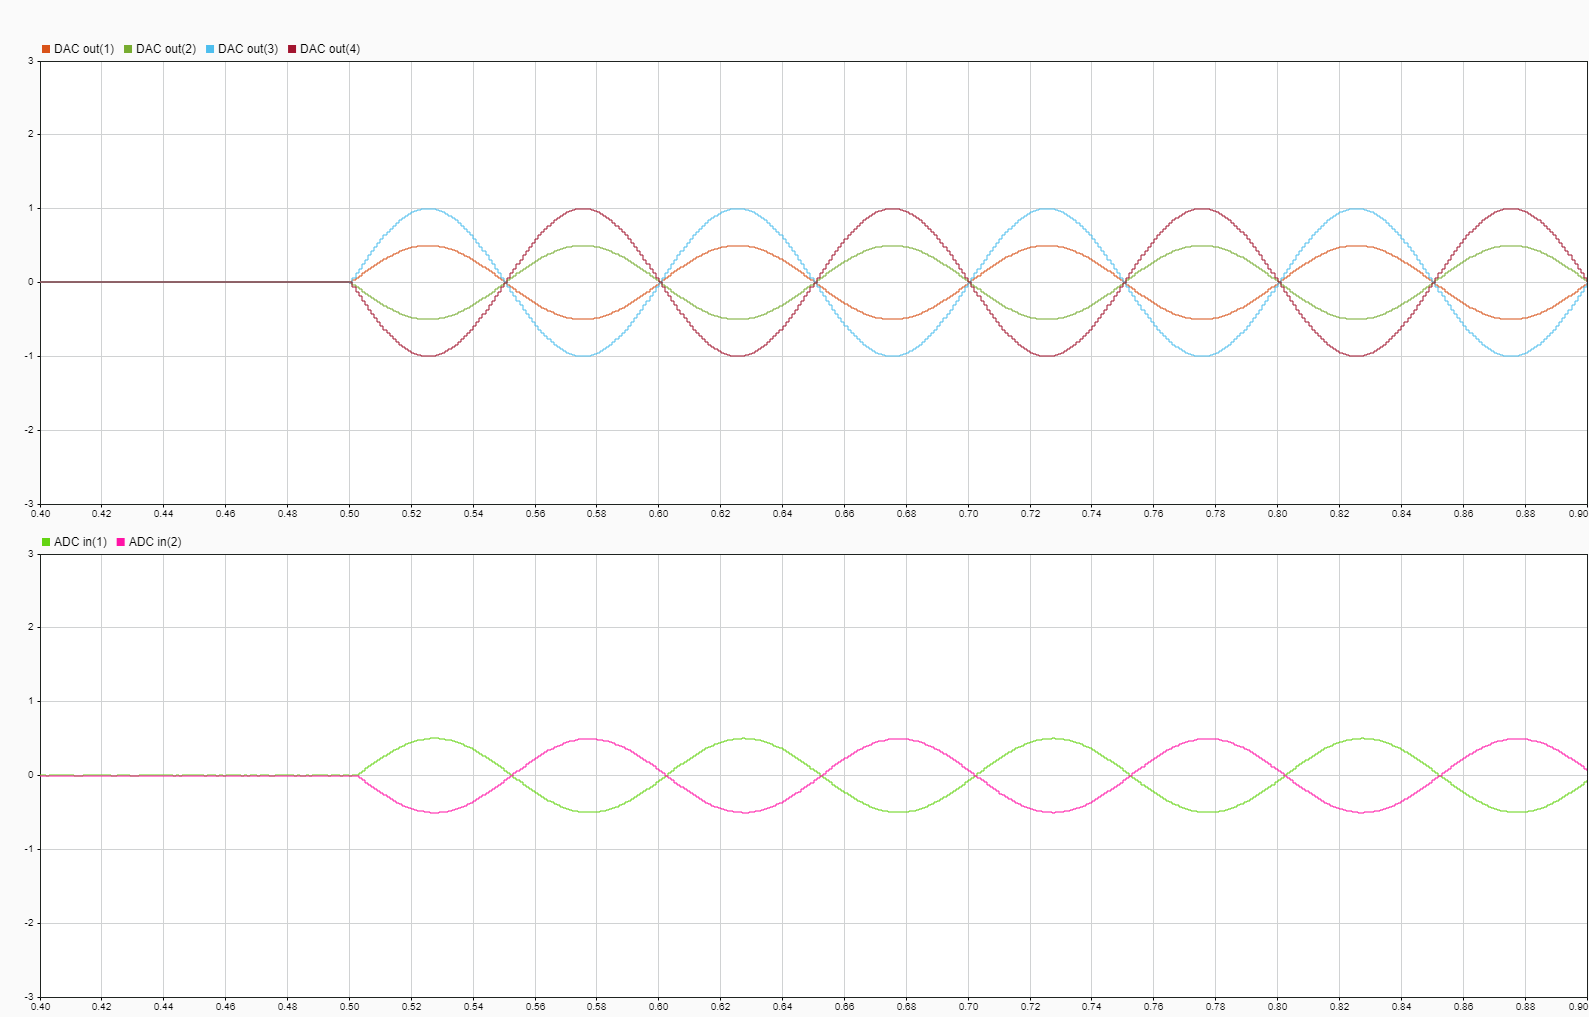

## Additional References

- [IO334 documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io334_325k)

- [Analog IO334](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_analog_io334_325k)